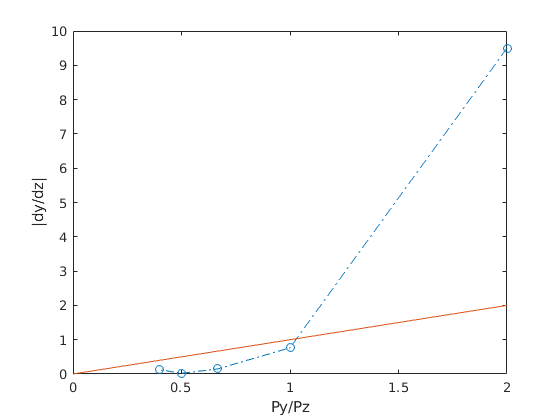

Py1 =[10,10,10,10,10];
Pz1 =[5,10,15,20,25];
Py2 =[5,10,15,20];
Pz2 = [15,15,15,15];
dy1 = [-38,-26,-10,2,16];
dy2 = [15,-9,-38,-64];
dz1 = [-4,-34,-68,-101,-131];
dz2 = [-80,-72,-56,-46];
phip1 = zeros(1,length(Py1));
phid1 = zeros(1,length(Py1));
avgphi1 = zeros(1,length(Py1));
PyByPz1 = zeros(1,length(Py1));
dyBydz1 = zeros(1,length(Py1));
phip2 = zeros(1,length(Py2));
phid2 = zeros(1,length(Py2));
avgphi2 = zeros(1,length(Py2));
PyByPz2 = zeros(1,length(Py2));
dyBydz2 = zeros(1,length(Py2));
for i = 1:length(Py1)
    phip1(i)= atan(Py1(i)/Pz1(i));
    phid1(i)= atan(dy1(i)/dz1(i));
    avgphi(i) =(phid1(i)+phip1(i))/2;
    PyByPz1(i) = (Py1(i)/Pz1(i));
    dyBydz1(i) = abs(dy1(i)/dz1(i));
end
clear i
for i = 1:length(Py2)
    phip2(i)= atan(Py2(i)/Pz2(i));
    phid2(i)= atan(dy2(i)/dz2(i));
    avgphi2(i) =(phid2(i)+phip2(i))/2;
    PyByPz2(i) = (Py2(i)/Pz2(i));
    dyBydz2(i) = abs(dy2(i)/dz2(i));
end
clear i
x=0:0.1:2;
y=x;
figure
grid on
plot(PyByPz1,dyBydz1,'-.o');
xlabel('Py/Pz');
ylabel('|dy/dz|');
hold on
plot(x,y);
hold off

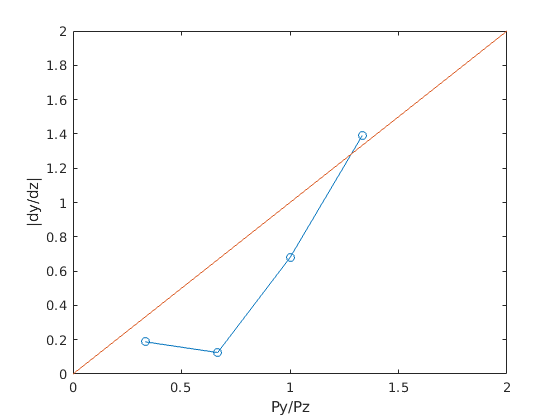

plot(PyByPz2,dyBydz2,'-o');
xlabel('Py/Pz');
ylabel('|dy/dz|');
hold on
plot(x,y);
hold off